# BME705: Rehabilitation Engineering

## Lab 2: Balance Board Signal Analysis

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BME705: Rehabilitation Engineering
% Lab 2: Balance Board Signal Analysis
%
% Created by: Dharmendra Gurve, 2020
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Names: Mohammad Tanvir Hassan, Ilina Petrova
%
% Student IDs: 501104056, i dont recall
%
clear all
close all

### PART 1

Plot the X and Y direction accelerometer data from the reference file with time on the x-axis and amplitude on y-axis.

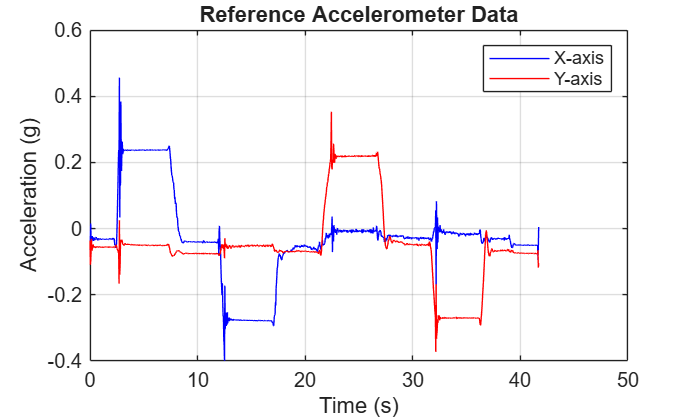

ref_data = xlsread( "Reference_Part1.xlsx" );

% Define sampling frequency 
fs = 30;


% Separate the sample_index from the excel file (column 1) to create time axis

% Define time
dlen = length(ref_data);
t= [0:dlen-1]/fs;

% Separate the X-axis and Y- axis from the excel file (column 2 and column 3)
% colum 1 is sample number
ref_X = ref_data(:, 2);
ref_Y = ref_data(:, 3);


%Plot the X and Y axis data against time as separate lines on the same grid
%plotting the x and y samples against t
plot(t, ref_X, 'b', t, ref_Y, 'r');
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Reference Accelerometer Data');
legend('X-axis', 'Y-axis');
grid on;

#### Start the signal from the actual activity

35 sec * 30 Hz = 1050 (+ start point) e.g. start point for referance file= 75

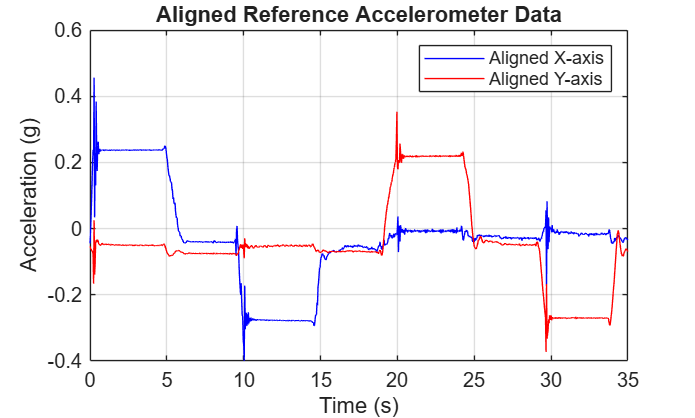

r1_start_point = 75; % Starting point for Subject 1
r1_X_aligned = ref_X(r1_start_point:end); % Aligning X-axis data
r1_Y_aligned = ref_Y(r1_start_point:end); % Aligning Y-axis data


% Define time
dlen = length(r1_X_aligned);
time_aligned = [0:dlen-1]/fs;


% plot the newly aligned reference X and Y axis data against time aligned
% Plot the aligned reference X and Y axis data against time aligned
% Set time limit to 35 seconds
time_limit = 35;
time_aligned = time_aligned(time_aligned <= time_limit);
r1_X_aligned = r1_X_aligned(1:length(time_aligned));
r1_Y_aligned = r1_Y_aligned(1:length(time_aligned));

figure;
plot(time_aligned, r1_X_aligned, 'b', time_aligned, r1_Y_aligned, 'r');
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Aligned Reference Accelerometer Data');
legend('Aligned X-axis', 'Aligned Y-axis');
grid on;


%%%%%%%%%% Measuring Signal Similarities using Cross-correlation between signals ref_X to sub_X, ref_Y to sub_Y 

#### Cross-correlation 

Determine and plot the cross-correlation between the reference file and each of the three subjects to show which subject is the most balanced

Calculate the correlation coefficient in each case and tabulate them.

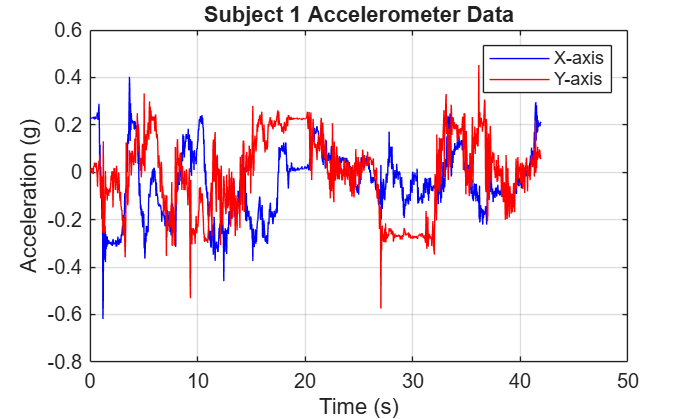

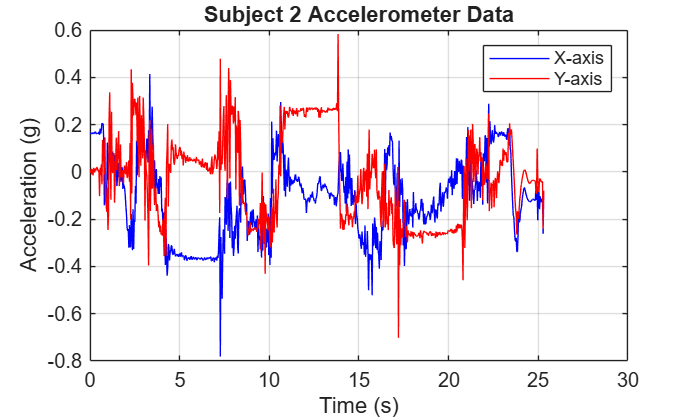

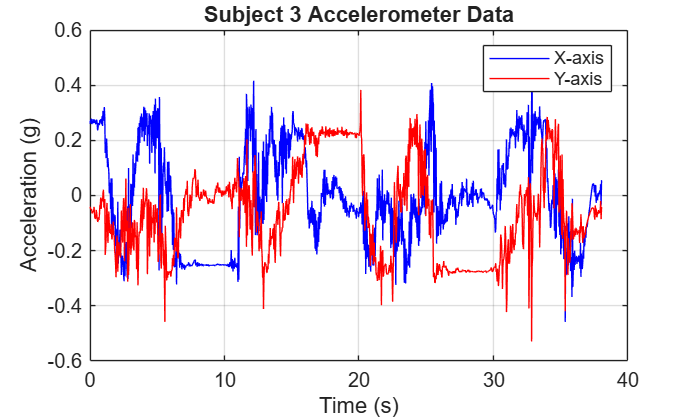

sub1_part1 = xlsread( "Subject1_Part1.xlsx" );
sub2_part1 = xlsread("Subject2_Part1.xlsx");
sub3_part1 = xlsread("Subject3_Part1.xlsx");

%Subject 1 data 
start_time_seconds = 21;% Change this according to the start time of the sample
s1_start_point = (30 * start_time_seconds);
s1_X_aligned = sub1_part1(s1_start_point:end, 2); % Aligning X-axis data for Subject 1
s1_Y_aligned = sub1_part1(s1_start_point:end, 3); % Aligning Y-axis data for Subject 1
dlen = length(s1_X_aligned);
time_s11 = [0:dlen-1]/fs;

%Subject 2 data
start_time_seconds2 = 12.5;
s2_start_point = 30 * start_time_seconds2;
s2_X_aligned = sub2_part1(s2_start_point:end, 2); % Aligning X-axis data for Subject 2
s2_Y_aligned = sub2_part1(s2_start_point:end, 3); % Aligning Y-axis data for Subject 2
dlen = length(s2_X_aligned);
time_s21 = [0:dlen-1]/fs;

%subject 3 data
start_time_seconds3 = 38.5+12.5;
s3_start_point = 30 * start_time_seconds3; % Aligning X-axis data for Subject 3
s3_X_aligned = sub3_part1(s3_start_point:end, 2); % Aligning X-axis data for Subject 3
s3_Y_aligned = sub3_part1(s3_start_point:end, 3); % Aligning Y-axis data for Subject 3
dlen = length(s3_X_aligned);
time_s31 = [0:dlen-1]/fs;

% Plotting Subject data in a loop
subjects = {s1_X_aligned, s1_Y_aligned; s2_X_aligned, s2_Y_aligned; s3_X_aligned, s3_Y_aligned};
time_data = {time_s11, time_s21, time_s31};
titles = {'Subject 1 Accelerometer Data', 'Subject 2 Accelerometer Data', 'Subject 3 Accelerometer Data'};

for i = 1:3
    figure;
    plot(time_data{i}, subjects{i, 1}, 'b', time_data{i}, subjects{i, 2}, 'r');
    xlabel('Time (s)');
    ylabel('Acceleration (g)');
    title(titles{i});
    legend('X-axis', 'Y-axis');
    grid on;
end


function correlate_signals(ref_X, ref_Y, sub_X, sub_Y, fs, plot_title)
    % Make the lengths of the reference and subject signals equal by truncating the longer signal
    min_length = min(length(ref_X), length(sub_X));
    ref_X = ref_X(1:min_length);
    sub_X = sub_X(1:min_length);
    ref_Y = ref_Y(1:min_length);
    sub_Y = sub_Y(1:min_length);

    % Find the cross-correlation between Subject and reference signals
    [r_X, lag_X]  = xcorr(ref_X, sub_X);
    [r_Y, lag_Y]  = xcorr(ref_Y, sub_Y);

    % Calculate the Correlation coefficients
    corr_X = corrcoef(ref_X, sub_X);
    corr_X_val = corr_X(1, 2);
    corr_Y = corrcoef(ref_Y, sub_Y);
    corr_Y_val = corr_Y(1, 2);
    fprintf('%s vs Reference correlation coefficient for X-axis: %.4f\n', plot_title, corr_X_val);
    fprintf('%s vs Reference correlation coefficient for Y-axis: %.4f\n', plot_title, corr_Y_val);

    % Plot the correlation overlap of x-axis    
    subplot(2, 1, 1);
    plot(lag_X/fs, r_X, 'LineWidth', 1.5, 'Color', 'b'); % Blue color for X-axis
    grid on;
    title([plot_title, ' Cross-Correlation of X-axis'], 'FontSize', 14, 'FontWeight', 'bold');
    xlabel("Time Lag (s)", 'FontSize', 12);
    ylabel("Correlation Coefficient", 'FontSize', 12);
    legend('Cross-Correlation', 'FontSize', 12);
    set(gca, 'FontSize', 12); % Increase font size for axes

    % Plot the correlation overlap of y-axis 
    subplot(2, 1, 2);
    plot(lag_Y/fs, r_Y, 'LineWidth', 1.5, 'Color', 'r'); % Red color for Y-axis
    grid on;
    title([plot_title, ' Cross-Correlation of Y-axis'], 'FontSize', 14, 'FontWeight', 'bold');
    xlabel("Time Lag (s)", 'FontSize', 12);
    ylabel("Correlation Coefficient", 'FontSize', 12);
    legend('Cross-Correlation', 'FontSize', 12);
    set(gca, 'FontSize', 12); % Increase font size for axes
end

% Call the function for Subject 1
correlate_signals(r1_X_aligned, r1_Y_aligned, s1_X_aligned, s1_Y_aligned, fs, "Subject 1");

Subject 1 vs Reference correlation coefficient for X-axis: 0.1163
Subject 1 vs Reference correlation coefficient for Y-axis: 0.2544


% Call the function for Subject 2
correlate_signals(r1_X_aligned, r1_Y_aligned, s2_X_aligned, s2_Y_aligned, fs, "Subject 2");

Subject 2 vs Reference correlation coefficient for X-axis: 0.0262
Subject 2 vs Reference correlation coefficient for Y-axis: -0.1168


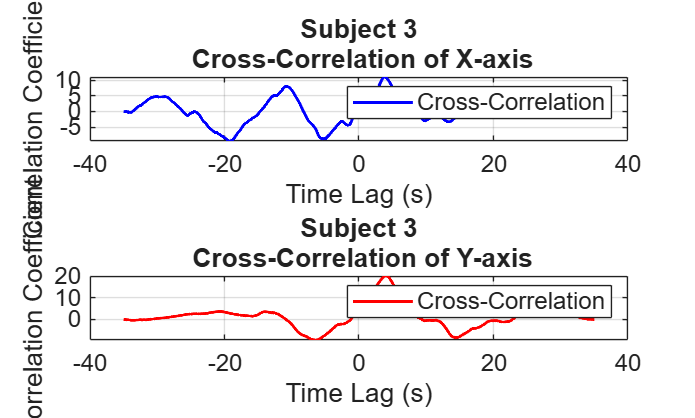

Subject 3 vs Reference correlation coefficient for X-axis: 0.1042
Subject 3 vs Reference correlation coefficient for Y-axis: 0.1353


% Call the function for Subject 3
correlate_signals(r1_X_aligned, r1_Y_aligned, s3_X_aligned, s3_Y_aligned, fs, "Subject 3");

## Part 2 

#### load the data from all subjects

Determine and plot the cross-correlation between the reference file and each of the three subjects to show which subject is the most balanced (x-axis of reference to x-axis of subject as well as y-axis of reference to y-axis of subjects).

Use the cross-correlation function to quantify the balance of each subject.

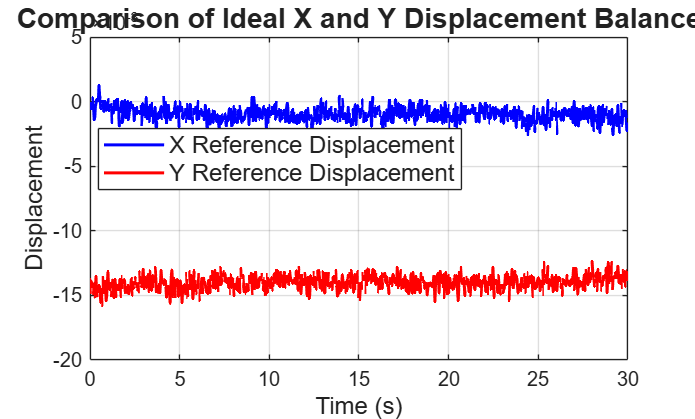

%% load the data from all subjects
ref_data = xlsread("Reference_Part2.xlsx");
sub1_part2 = xlsread("Subject1_Part2.xlsx");
sub2_part2 = xlsread("Subject2_Part2.xlsx");
sub3_part2 = xlsread("Subject3_Part2.xlsx");
% Separate the X-axis and Y-axis from the excel file (column 2 and column 3)
ref_X = ref_data(:, 2);
ref_Y = ref_data(:, 3);
sub1_X = sub1_part2(:, 2);
sub1_Y = sub1_part2(:, 3);
sub2_X = sub2_part2(:, 2);
sub2_Y = sub2_part2(:, 3);
sub3_X = sub3_part2(:, 2);
sub3_Y = sub3_part2(:, 3);
t_new = (0:(30*30)-1)/30;
figure;
plot(t_new, ref_X, 'LineWidth', 1.5, 'Color', 'b'); % Blue for X Reference
hold on;
plot(t_new, ref_Y, 'LineWidth', 1.5, 'Color', 'r'); % Red for Y Reference
grid on;
legend("X Reference Displacement", "Y Reference Displacement", 'Location', 'best', 'FontSize', 12);
title("Comparison of Ideal X and Y Displacement Balance", 'FontSize', 14, 'FontWeight', 'bold');
xlabel("Time (s)", 'FontSize', 12);
ylabel("Displacement", 'FontSize', 12);
hold off;

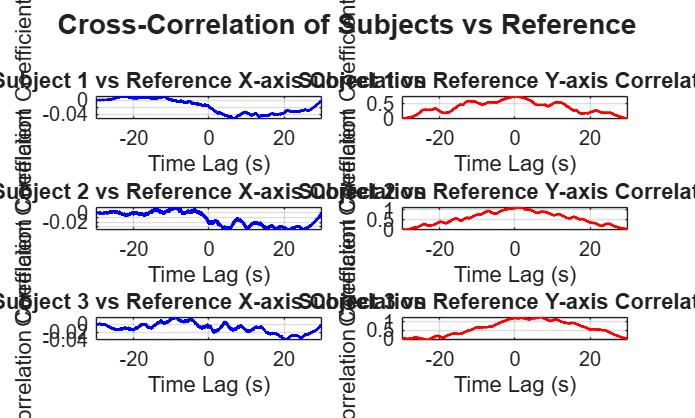

% Subject 1
[r_X, lag_X] = xcorr(ref_X, sub1_X);
[r_Y, lag_Y] = xcorr(ref_Y, sub1_Y);
subplot(3, 2, 1);
plot(lag_X/fs, r_X, 'LineWidth', 1.5, 'Color', 'b'); % Blue for X-axis
grid on;
title("Subject 1 vs Reference X-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes
subplot(3, 2, 2);
plot(lag_Y/fs, r_Y, 'LineWidth', 1.5, 'Color', 'r'); % Red for Y-axis
grid on;
title("Subject 1 vs Reference Y-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes

% Subject 2
[r_X, lag_X] = xcorr(ref_X, sub2_X);
[r_Y, lag_Y] = xcorr(ref_Y, sub2_Y);
subplot(3, 2, 3);
plot(lag_X/fs, r_X, 'LineWidth', 1.5, 'Color', 'b'); % Blue for X-axis
grid on;
title("Subject 2 vs Reference X-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes
subplot(3, 2, 4);
plot(lag_Y/fs, r_Y, 'LineWidth', 1.5, 'Color', 'r'); % Red for Y-axis
grid on;
title("Subject 2 vs Reference Y-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes

% Subject 3
[r_X, lag_X] = xcorr(ref_X, sub3_X);
[r_Y, lag_Y] = xcorr(ref_Y, sub3_Y);
subplot(3, 2, 5);
plot(lag_X/fs, r_X, 'LineWidth', 1.5, 'Color', 'b'); % Blue for X-axis
grid on;
title("Subject 3 vs Reference X-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes
subplot(3, 2, 6);
plot(lag_Y/fs, r_Y, 'LineWidth', 1.5, 'Color', 'r'); % Red for Y-axis
grid on;
title("Subject 3 vs Reference Y-axis Correlation", 'FontSize', 12, 'FontWeight', 'bold');
xlabel("Time Lag (s)", 'FontSize', 10);
ylabel("Correlation Coefficient", 'FontSize', 10);
set(gca, 'FontSize', 10); % Increase font size for axes
sgtitle("Cross-Correlation of Subjects vs Reference", 'FontSize', 14, 'FontWeight', 'bold');

## Calculate RMSE between Ref file and subject files (X-X,Y-Y)

Calculate the root mean squared error (R.M.S E) for each subject (for both the X and Y direction) and state the values in the report. What do these indicate?

sub1_X_rmse = rmse(ref_X, sub1_X);
sub1_Y_rmse = rmse(ref_Y, sub1_Y);
sub2_X_rmse = rmse(ref_X, sub2_X);
sub2_Y_rmse = rmse(ref_Y, sub2_Y);
sub3_X_rmse = rmse(ref_X, sub3_X);
sub3_Y_rmse = rmse(ref_Y, sub3_Y);
subjects = {'Subject 1'; 'Subject 2'; 'Subject 3'};
rmse_X_values = [sub1_X_rmse; sub2_X_rmse; sub3_X_rmse];
rmse_Y_values = [sub1_Y_rmse; sub2_Y_rmse; sub3_Y_rmse];
rmse_table = table(subjects, rmse_X_values, rmse_Y_values, 'VariableNames', {'Subject', 'RMSE_X', 'RMSE_Y'});
disp(rmse_table);

       Subject       RMSE_X     RMSE_Y 
    _____________    _______    _______

    {'Subject 1'}    0.14131    0.13243
    {'Subject 2'}    0.16281    0.18245
    {'Subject 3'}    0.17141    0.18505



## Stabilogram of Subject

Plot a stabilogram of each of the three subjects. This is a graphical representation of the movements of the subject centered at zero. For this, divide the data array by the signal length (this aligns to center of pressure), then multiply it by a stretching factor and plot the X and Y direction data from the accelerometer as the X and Y axis of a graph. You may have to manually set the axis boundaries of your stabilogram to make it more visible, depending on your matlab display settings.

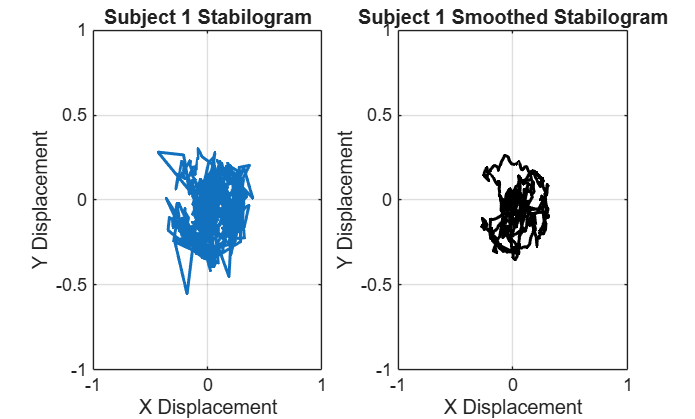

stretching_factor = 1000;
% Subject 1 Stabilogram
sub1_X_cop = (sub1_X / length(sub1_X)) * stretching_factor;
sub1_Y_cop = (sub1_Y / length(sub1_Y)) * stretching_factor;
figure;

subplot(1, 2, 1); % Create a subplot for the actual stabilogram
plot(sub1_X_cop, sub1_Y_cop, 'LineWidth', 1.5);
title("Subject 1 Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

subplot(1, 2, 2); % Create a subplot for the smoothed stabilogram
smooth_sub1_X_cop = smooth(sub1_X_cop);
smooth_sub1_Y_cop = smooth(sub1_Y_cop);
plot(smooth_sub1_X_cop, smooth_sub1_Y_cop, 'LineWidth', 1.5, 'Color', 'k'); % Smoothed line
title("Subject 1 Smoothed Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

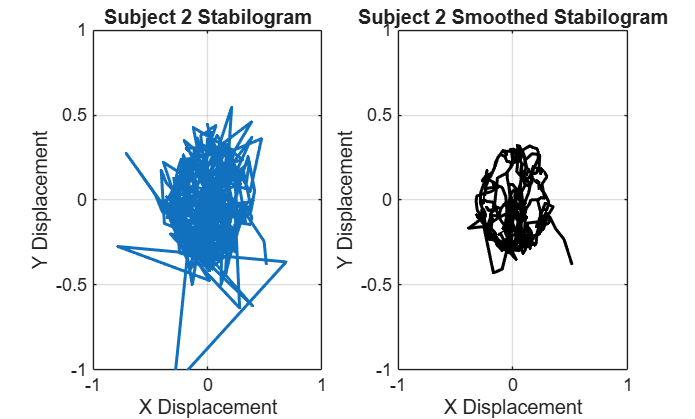


% Subject 2 Stabilogram
sub2_X_cop = (sub2_X / length(sub2_X)) * stretching_factor;
sub2_Y_cop = (sub2_Y / length(sub2_Y)) * stretching_factor;
figure;

subplot(1, 2, 1); % Create a subplot for the actual stabilogram
plot(sub2_X_cop, sub2_Y_cop, 'LineWidth', 1.5);
title("Subject 2 Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

subplot(1, 2, 2); % Create a subplot for the smoothed stabilogram
smooth_sub2_X_cop = smooth(sub2_X_cop);
smooth_sub2_Y_cop = smooth(sub2_Y_cop);
plot(smooth_sub2_X_cop, smooth_sub2_Y_cop, 'LineWidth', 1.5, 'Color', 'k'); % Smoothed line
title("Subject 2 Smoothed Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

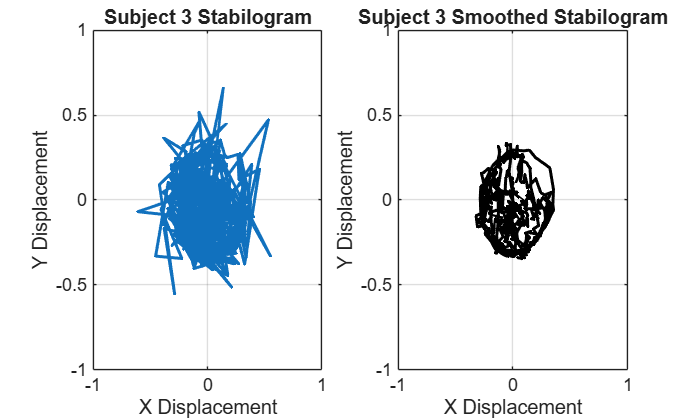


% Subject 3 Stabilogram
sub3_X_cop = (sub3_X / length(sub3_X)) * stretching_factor;
sub3_Y_cop = (sub3_Y / length(sub3_Y)) * stretching_factor;
figure;

subplot(1, 2, 1); % Create a subplot for the actual stabilogram
plot(sub3_X_cop, sub3_Y_cop, 'LineWidth', 1.5);
title("Subject 3 Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

subplot(1, 2, 2); % Create a subplot for the smoothed stabilogram
smooth_sub3_X_cop = smooth(sub3_X_cop);
smooth_sub3_Y_cop = smooth(sub3_Y_cop);
plot(smooth_sub3_X_cop, smooth_sub3_Y_cop, 'LineWidth', 1.5, 'Color', 'k'); % Smoothed line
title("Subject 3 Smoothed Stabilogram");
xlabel("X Displacement");
ylabel("Y Displacement");
grid on;
xlim([-1, 1]); % Set fixed x-axis limits
ylim([-1, 1]); % Set fixed y-axis limits

## Part 3

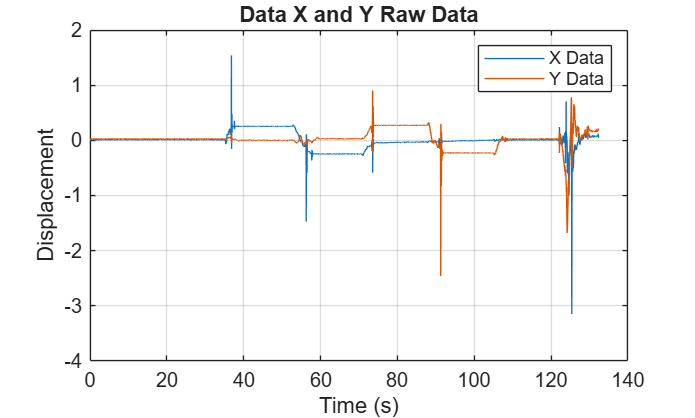

data = csvread("AccelerometerUncalibrated1.csv", 1, 0);
fs = 30;
data_x = data(:, 5);
data_y = -data(:, 4);
t = (0:length(data_x)-1) / fs;
figure;
plot(t, data_x, 'DisplayName', 'X Data');
hold on;
plot(t, data_y, 'DisplayName', 'Y Data');
hold off;
grid on;
legend show;
xlabel('Time (s)');
ylabel('Displacement');
title('Data X and Y Raw Data');

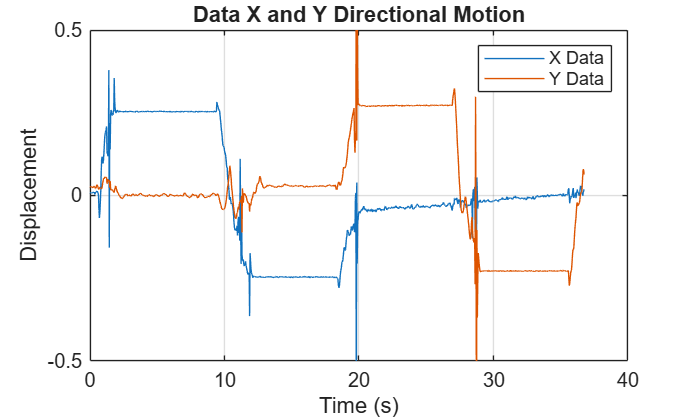

%% 3.5
% align directional motion at 34.667s
data_directional_motion_start_point = ceil(fs*34);
data_directional_motion_end_point = 1050*2.1 + data_directional_motion_start_point;
data_x_aligned = data_x(data_directional_motion_start_point:data_directional_motion_end_point);
data_y_aligned = data_y(data_directional_motion_start_point:data_directional_motion_end_point);
t_directional_motion = (0:length(data_x_aligned)-1) / fs;
data_x_downsampled = downsample(data_x_aligned, round(2.1));
data_y_downsampled = downsample(data_y_aligned, round(2.1));
t_downsampled = (0:length(data_x_downsampled)-1) / fs;
figure;
plot(t_downsampled, data_x_downsampled, 'DisplayName', 'X Data');
hold on;
plot(t_downsampled, data_y_downsampled, 'DisplayName', 'Y Data');
hold off;
grid on;
legend show;
xlabel('Time (s)');
ylabel('Displacement');
title('Data X and Y Directional Motion');
ylim([-0.5, 0.5]); % Set displacement limits to -0.5 to 0.5

data_x_aligned = data_x_downsampled(1:1051);
data_y_aligned = data_y_downsampled(1:1051);

ref_data = xlsread("Reference_Part1.xlsx");
% Separate the X-axis and Y- axis from the excel file (column 2 and column 3)
ref_X = ref_data(:, 2);
ref_Y = ref_data(:, 3);
% 35 sec * 30 Hz = 1050 (+ start point) e.g. start point for referance file= 75
start_index = 75;
end_index = 1050 + start_index;
ref_X_aligned = ref_X(start_index:end_index);
ref_Y_aligned = ref_Y(start_index:end_index);
% cross-correlation analysis
[r_X, lag_X]  = xcorr(ref_X_aligned, data_x_aligned);
[r_Y, lag_Y]  = xcorr(ref_Y_aligned, data_y_aligned);
% Calculate the Correlation coefficients
corr_X = corrcoef(ref_X_aligned, data_x_aligned);
corr_X_val = corr_X(1, 2);
corr_Y = corrcoef(ref_Y_aligned, data_y_aligned);
corr_Y_val = corr_Y(1, 2);
disp(['Data vs Reference correlation coefficient for X-axis Directional Motion: ', num2str(corr_X_val)]);

Data vs Reference correlation coefficient for X-axis Directional Motion: 0.60978


disp(['Data vs Reference correlation coefficient for Y-axis Directional Motion: ', num2str(corr_Y_val)]);

Data vs Reference correlation coefficient for Y-axis Directional Motion: 0.8149


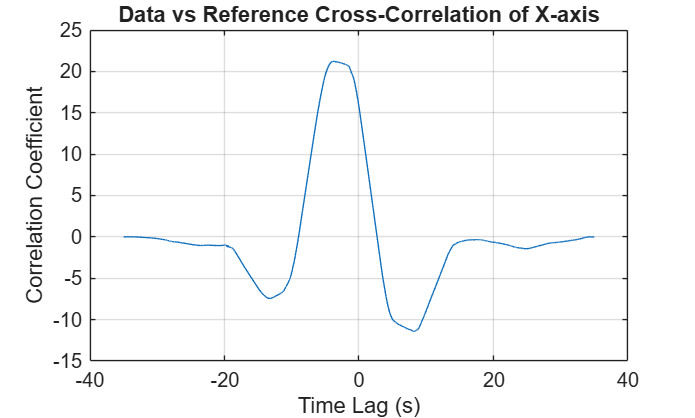

% Plot the correlation overlap of x-axis   
figure;
plot(lag_X/fs, r_X);
grid on;
title("Data vs Reference Cross-Correlation of X-axis");
xlabel("Time Lag (s)");
ylabel("Correlation Coefficient");

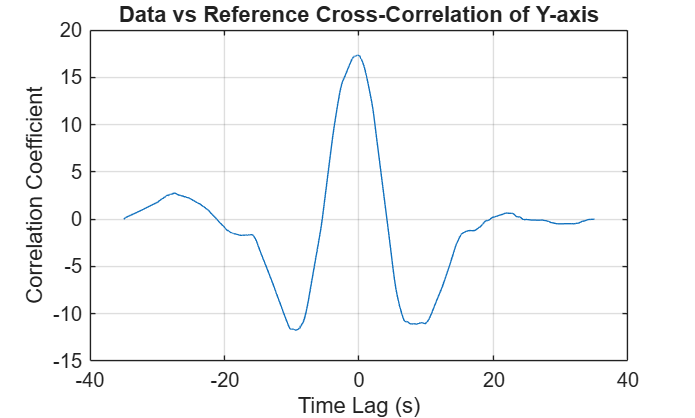

% Plot the correlation overlap of y-axis
figure;
plot(lag_Y/fs, r_Y);
grid on;
title("Data vs Reference Cross-Correlation of Y-axis");
xlabel("Time Lag (s)");
ylabel("Correlation Coefficient");

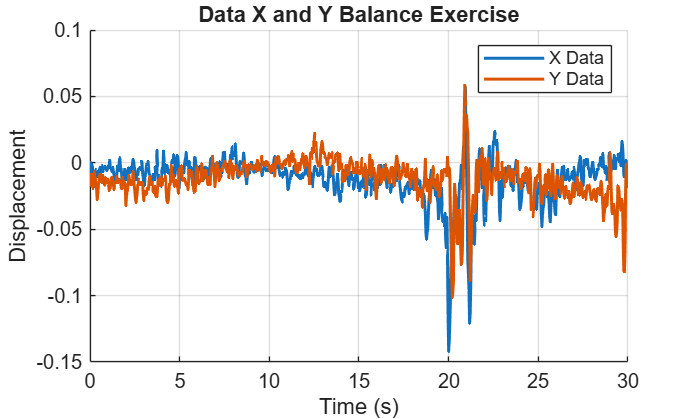

data3 = csvread("AccelerometerUncalibrated22.csv", 1, 0);
data_x = data3(:, 5);
data_y = data3(:, 4);
data_x_balance_exercise = data_x(data_directional_motion_end_point:data_directional_motion_end_point+(30*fs)-1);
data_y_balance_exercise = data_y(data_directional_motion_end_point:data_directional_motion_end_point+(30*fs)-1);
t_balance_exercise = (0:length(data_x_balance_exercise)-1) / fs;
figure;
hold on;
plot(t_balance_exercise, data_x_balance_exercise, 'DisplayName', 'X Data', 'LineWidth', 1.5);
plot(t_balance_exercise, data_y_balance_exercise, 'DisplayName', 'Y Data', 'LineWidth', 1.5);
hold off;
grid on;
legend show;
xlabel('Time (s)');
ylabel('Displacement');
title('Data X and Y Balance Exercise');

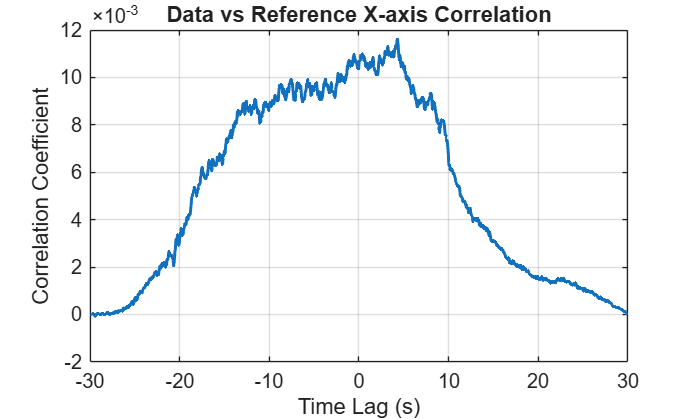

ref_data = xlsread("Reference_Part2.xlsx");
% Separate the X-axis and Y-axis from the excel file (column 2 and column 3)
ref_X = ref_data(:, 2);
ref_Y = ref_data(:, 3);
[r_X, lag_X] = xcorr(ref_X, data_x_balance_exercise);
[r_Y, lag_Y] = xcorr(ref_Y, data_y_balance_exercise);
figure;
plot(lag_X/fs, r_X, 'LineWidth', 1.5);
grid on;
title("Data vs Reference X-axis Correlation");
xlabel("Time Lag (s)");
ylabel("Correlation Coefficient");

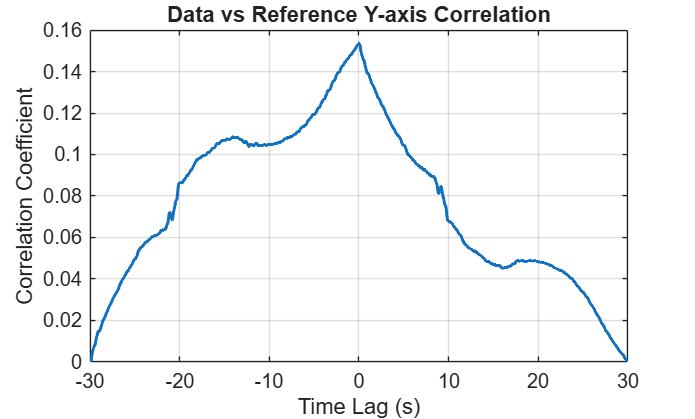

figure;
plot(lag_Y/fs, r_Y, 'LineWidth', 1.5);
grid on;
title("Data vs Reference Y-axis Correlation");
xlabel("Time Lag (s)");
ylabel("Correlation Coefficient");

X_rmse = rmse(ref_X, data_x_balance_exercise);
Y_rmse = rmse(ref_Y, data_y_balance_exercise);
disp(['Data vs Reference RMSE for X-axis Balance: ', num2str(X_rmse)]);

Data vs Reference RMSE for X-axis Balance: 0.020422


disp(['Data vs Reference RMSE for Y-axis Balance: ', num2str(Y_rmse)]);

Data vs Reference RMSE for Y-axis Balance: 0.014822
